## MATLAB Problem 7.54

Use the MATLAB command **zplane** to obtain a pole-zero plot for the following systems:

(a) $H(z)=\frac {1+z^{-2}} {2+z^{-1}-1/2z^{-2}+1/4z^{-3}}=\frac {z^3+z} {2z^3+z^2-1/2z+1/4}$

(b) $H(z)=\frac {1+z^{-1}+3/2z^{-2}+1/2z^{-3}} {1+3/2z^{-1}-1/2z^{-2}}=\frac {z^3+z^{2}+3/2z+1/2} {z^3+3/2z^{2}-1/2z}$

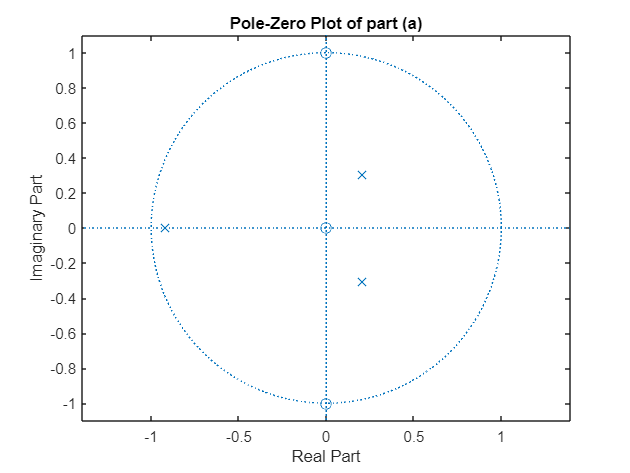

% (a)
figure(2); clf; clear; clc; format compact
num = [1 0 1 0];
den = [2 1 -1/2 1/4];
zplane(num,den)
title('Pole-Zero Plot of part (a)')

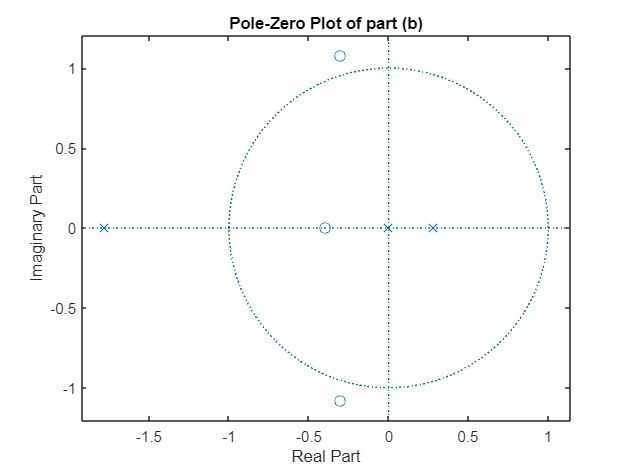


% (b)
figure(2); clf; clear; clc; format compact
num = [1 1 3/2 1/2];
den = [1 3/2 -1/2 0]; 
zplane(num,den)
title('Pole-Zero Plot of part (b)')

## MATLAB Problem 7.55

Use the MATLAB command **residuez** to obtain the partial-fraction expansions required to solve Problem 7.24(d)-(g).

(d) $X(z)=\frac {z^{2}-3z} {z^{2}+3/2z-1}, 1/2 <|z|<2$

(e) $X(z)=\frac {3z^{2}-1/4z} {z^2-16}, |z|>4$

(f) $X(z)=\frac {z^3+z^2+3/2z+1/2} {z^3+3/2z^2+1/2z}, |z|<1/2$

(g) $X(z)=\frac {2z^4-2z^3-2z^2}  {z^2-1}, |z| >1$

format compact
clc
clear
num=[1 -3]

num =      1.0000e+000    -3.0000e+000


den=[1 3/2 -1]

den =      1.0000e+000     1.5000e+000    -1.0000e+000


[d_R, d_P, d_K] = residuez(num,den)

d_R =      2.0000e+000
    -1.0000e+000


d_P =     -2.0000e+000
   500.0000e-003


d_K =
     []



format compact
clc
clear
num=[3 -1/4]

num =      3.0000e+000  -250.0000e-003


den=[1 0 -16]

den =      1.0000e+000     0.0000e+000   -16.0000e+000


[e_R, e_P, e_K] = residuez(num,den)

e_R =      1.4688e+000
     1.5312e+000


e_P =      4.0000e+000
    -4.0000e+000


e_K =
     []



format compact
clc
clear
num=[1 1 3/2 1/2]

num =      1.0000e+000     1.0000e+000     1.5000e+000   500.0000e-003


den=[1 3/2 1/2]

den =      1.0000e+000     1.5000e+000   500.0000e-003


[f_R, f_P, f_K] = residuez(num,den)

f_R =      2.0000e+000
    -1.0000e+000


f_P =     -1.0000e+000
  -500.0000e-003


f_K =      0.0000e+000     1.0000e+000



format compact
clc
clear
num=[2 -2 -2]

num =      2.0000e+000    -2.0000e+000    -2.0000e+000


den=[1 0 -1]

den =      1.0000e+000     0.0000e+000    -1.0000e+000


[g_R, g_P, g_K] = residuez(num,den)

g_R =      1.0000e+000
    -1.0000e+000


g_P =     -1.0000e+000
     1.0000e+000


g_K =      2.0000e+000